%set up index to only pull sites with phenocams from fluxnet
fn=fuf(['/Users/kdw223/Google Drive/Research/NZ_Method/2015FLUXDATA/']);%you will have to change this to your filepath
fn=fn(2:end, :);
raw=[]


raw =

     []



z=[]


z =

     []



r=[]


r =

     []



p=[]


p =

     []



pieces = regexp(fn, '_', 'split');

for jj=1:length(fn)
AllC = {cat(1, pieces{jj}{2})};
sitename{jj}=AllC;
end

for i=1:length(sitename);
site(i)=sitename{i};
end
site=site';
phenoSites=importfile2('phenoSites.txt')

phenoSites = 528×35 table
              site                 lat        lon      elev                                 contact1                                                           contact2                              date_start     date_end       nimage      tzoffset    active    infrared     method                                                                site_description                                                                                           group                                                       camera_description                            camera_orientation    site_type    flux_data              flux_networks           

sites=phenoSites.flux_sitenames

sites = 528×1 string array
    ""
    ""
    ""
    ""
    ""
    "US-NC4"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    "US-Rws"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    "US-SP1"
    ""
    ""
    "PA-Bar"
    "PA-Bar"
    "PA-Bar"
    ""
    "US-Bar"
    "US-Bar"
    "US-Ha1"
    "US-Ha1"
    "Harvard Barn Tower"
    "Harvard Barn Tower"
    ""
    ""
    "US-Bar"
    ""
    ""
    ""
    "IT-BCi"
    "IT-BCi"
    ""
    ""
    "US-Bi1"
    "US-Bi2"
    ""
    "US-MTB (forthcoming)"
    ""
    ""
    ""
    "US-BdA"
    "US-BdC"
    ""
    ""
    ""
    ""
    ""
    ""
    "Ca-Oas"
    ""
    "Ca-Obs"
    ""
    "No"
    ""
    "Ca-Qfo"
    ""
    "US-MOz"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    "ES-FtD"
    ""
    ""
    ""
    ""
    "US-Dk2"
    "US-Tw4"
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    ""
    "US-FR1"
  

idx=ismember(site, sites);
fn=fn(idx)

fn = 28×1 cell array
    'FLX_AT-Neu_FLUXNET2015_SUBSET_DD_2002-2012_1-2.csv'
    'FLX_CA-Gro_FLUXNET2015_SUBSET_DD_2003-2014_1-2.csv'
    'FLX_CA-TP1_FLUXNET2015_SUBSET_DD_2002-2014_2-3.csv'
    'FLX_CA-TP4_FLUXNET2015_SUBSET_DD_2002-2014_1-3.csv'
    'FLX_CA-TPD_FLUXNET2015_SUBSET_DD_2012-2014_1-2.csv'
    'FLX_IT-BCi_FLUXNET2015_SUBSET_DD_2004-2014_2-3.csv'
    'FLX_IT-MBo_FLUXNET2015_SUBSET_DD_2003-2013_1-3.csv'
    'FLX_IT-Tor_FLUXNET2015_SUBSET_DD_2008-2014_2-3.csv'
    'FLX_US-ARM_FLUXNET2015_SUBSET_DD_2003-2012_1-2.csv'
    'FLX_US-CRT_FLUXNET2015_SUBSET_DD_2011-2013_1-2.csv'
    'FLX_US-Ha1_FLUXNET2015_SUBSET_DD_1991-2012_1-2.csv'
    'FLX_US-Ivo_FLUXNET2015_SUBSET_DD_2004-2007_1-2.csv'
    'FLX_US-Los_FLUXNET2015_SUBSET_DD_2000-2014_2-3.csv'
    'FLX_US-MMS_FLUXNET2015_SUBSET_DD_1999-2014_1-2.csv'
    'FLX_US-Me2_FLUXNET2015_SUBSET_DD_2002-2014_1-2.csv'
    'FLX_US-Me6_FLUXNET2015_SUBSET_DD_2010-2014_2-2.csv'
    'FLX_US-Myb_FLUXNET2015_SUBSET_DD_2010-2014_2-3.csv'
    'FLX_U

[sitedataH]=processAmeriflux(fn(6)) %example of GPP from a single random site

sitedataH =    1.0e+07 *

    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002         0
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002         0
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002         0
    2.0041    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000
    2.

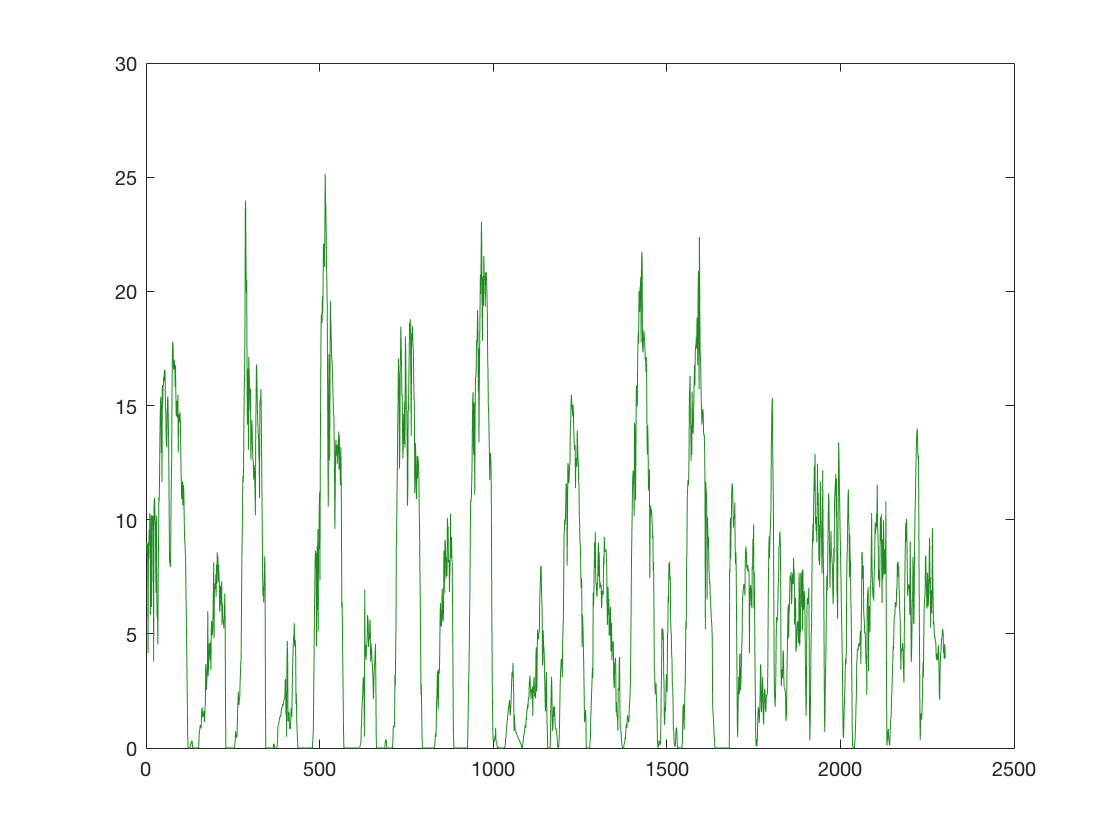

figure, plot(sitedataH(:, 4), '-', 'Color', rgb('forestgreen'))